clc;
clear;
amplitude = 1000;
titulo = sprintf("Resposta degrau com amplitude %d", amplitude);

%VÁLVULA
numv = 1;
denv = [1 0];
val = tf(numv, denv)

val =
 
  1
  -
  s
 
Continuous-time transfer function.
Model Properties



%TANQUE
numt = 1;
dent = [1 2];
tanqu = tf(numt, dent)

tanqu =
 
    1
  -----
  s + 2
 
Continuous-time transfer function.
Model Properties


tanquC =
 
   1
  ---
  s^2
 
Continuous-time transfer function.
Model Properties



%REDUÇÃO DE BLOCOS
G1 = series(val, tanqu);
G = feedback(G1, 1)

G =
 
        1
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.
Model Properties


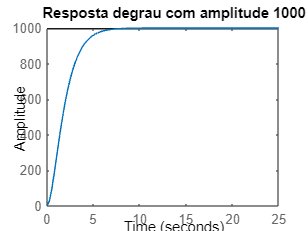


%RESPOSTA DO SISTEMA 1
step(G*amplitude, 25) %esse número pós virgula é o eixo x
title(titulo);

a = dcgain(G1);
erro = 1/(1+a)

erro = 0

stepinfo(G*amplitude)

ans = struct with fields:
         RiseTime: 3.3579
    TransientTime: 5.8339
     SettlingTime: 5.8339
      SettlingMin: 900.0223
      SettlingMax: 999.3957
        Overshoot: 0
       Undershoot: 0
             Peak: 999.3957
         PeakTime: 9.7900


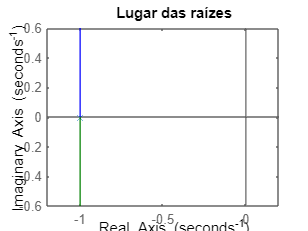

figure;
rlocus(G*amplitude)
title("Lugar das raízes"); %o valor não muda, pois não precisa depende do STEP